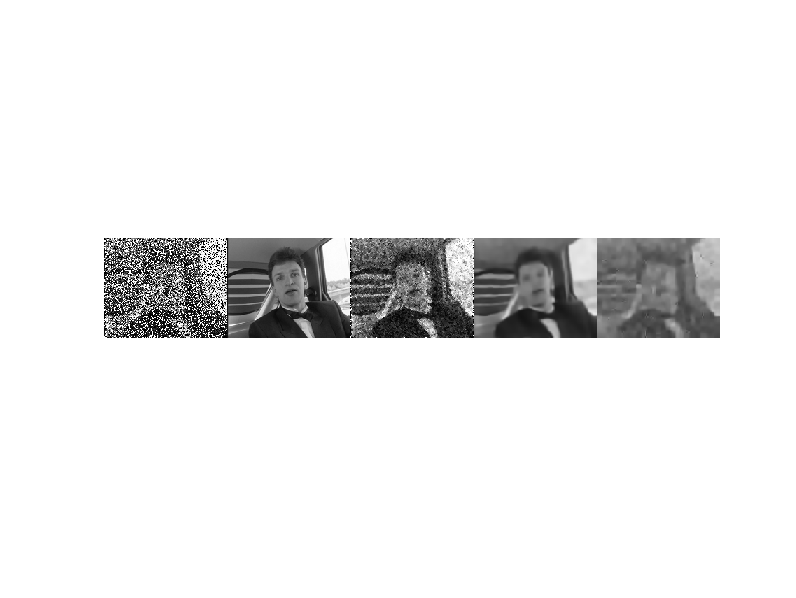

clc;
clear;
close all;

addpath("BM3D");

vid = yuv4mpeg2mov('../Test_Videos/carphone.y4m');

[n1,n2,~]=size(vid(1).cdata);
no_of_frames= 50; 
frame_num=20;
tau = 1.2;
iters=30;
frames= uint8(zeros([n1 n2 no_of_frames]));
noisy_frames= uint8(zeros([n1 n2 no_of_frames]));
filtered_frames= uint8(zeros([n1 n2 no_of_frames]));

for i=1:no_of_frames
    frames(:,:,i)= rgb2gray(vid(i).cdata);
    noisy_frames(:,:,i) = noise(frames(:,:,i), 10, 1, 0.1);
    filtered_frames(:,:,i) = adaptive_median_filter(noisy_frames(:,:,i),10);
end

[~, Y_filter]= VBM3D(filtered_frames,120, 0, 0); %Using the BM3D library downloaded from the internet.
Y_filter=Y_filter*255;
[~, Y_no_filter]= VBM3D(noisy_frames,120, 0, 0); %Using the BM3D library downloaded from the internet.
Y_no_filter=Y_no_filter*255;

figure; imshow([noisy_frames(:,:,frame_num) frames(:,:,frame_num) filtered_frames(:,:,frame_num) Y_filter(:,:,frame_num) Y_no_filter(:,:,frame_num)])


PSNR_filter = 20*log10(255*sqrt(n1*n2)/norm(double(Y_filter(:,:,frame_num)) - double(frames(:,:,frame_num)),'fro'))

PSNR_filter = 23.2361

PSNR_no_filter = 20*log10(255*sqrt(n1*n2)/norm(double(Y_no_filter(:,:,frame_num)) - double(frames(:,:,frame_num)),'fro'))

PSNR_no_filter = 15.7141

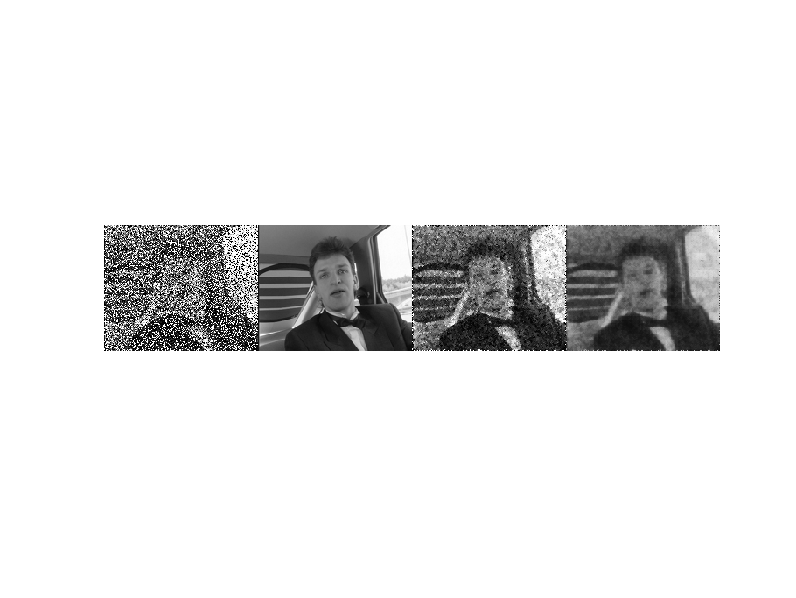


missing_pixels = (filtered_frames == noisy_frames); %Finding missing pixels due to corruption by impulsive noise
patches = uint8(zeros([8*8 n1/4-1 n2/4-1 no_of_frames]));
missing = false([8*8 n1/4-1 n2/4-1 no_of_frames]);

for i=no_of_frames
    for j=1:n1
        mean_row = mean(double(filtered_frames(j,:,i)));
        std_row = std(double(filtered_frames(j,:,i)));
        for k=1:n2
            if(missing_pixels(j,k,i) > mean_row + 2*std_row || missing_pixels(j,k,i) < mean_row - 2*std_row) %For second subset of missing values
                missing_pixels(j,k,i)=false;
            end
        end
    end
end

for i=1:no_of_frames
   for j = 1:(n1/4-1)
       for k = 1:(n2/4-1)
           patches(:,j,k,i) = reshape(filtered_frames(4*(j-1)+1:4*(j-1)+8 , 4*(k-1)+1:4*(k-1)+8, i), [64 1]);
           missing(:,j,k,i) = reshape(missing_pixels(4*(j-1)+1:4*(j-1)+8 , 4*(k-1)+1:4*(k-1)+8, i), [64 1]);    
       end
   end
end

denoised_patches = double(zeros([8*8 n1/4-1 n2/4-1 no_of_frames]));
for j=1:n1/4-1
    for k=1:n2/4-1
        [patch_matrix, Omega, find]=patchmatcher(patches,j,k,frame_num,missing);
        denoised_patch = fixed_point_iteration(patch_matrix,Omega,tau,iters,find,no_of_frames);
        patches(:, j, k, frame_num) = denoised_patch;
        denoised_patches(:,j,k,frame_num) = denoised_patch;
    end
end
recon=double(zeros([n1,n2]));
count=double(zeros([n1,n2]));
for j=1:n1/4-1
        for k=1:n2/4-1
            recon(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) =  recon(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) + reshape(denoised_patches(:,j,k,frame_num),[8 8]);
            count(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) = count(4*(j-1)+1:4*(j+1),4*(k-1)+1:4*(k+1)) + 1;
        end
end
recon = uint8(recon./count);
figure; 
imshow([noisy_frames(:,:,frame_num) frames(:,:,frame_num) filtered_frames(:,:,frame_num) recon]);

PSNR_FTI = 20*log10(255*sqrt(n1*n2)/norm(double(recon) - double(frames(:,:,frame_num)), 'fro'))

PSNR_FTI = 19.9606